clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',false,'Display','iter');

%x0 = [15.7329	0.4169	0.0333	-5.3921	9.8840	-5.4486] + 5;

lb = [0 0 0 -10 -10 -10];
ub = [30 30 30 10 10 10];

x0 = lb +(ub - lb).*lhsdesign(6,1)';%[10 8/3 28 1 1 1];

tic
[xv,Rv] = fmincon(@(x) objective(x),x0,[],[],[],[],lb,ub,[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    1.292269e+02    0.000e+00    2.310e+01
    1      14    6.745692e+01    0.000e+00    2.323e+03    7.615e+00
    2      21    6.733682e+00    0.000e+00    5.360e+05    3.262e+00
    3      30    5.968941e+00    0.000e+00    3.588e+05    1.695e+00
    4      37    5.330256e-01    0.000e+00    6.427e+05    2.615e+01
    5      52    5.260423e-01    0.000e+00    2.802e+02    6.180e-02
    6      70    5.257994e-01    0.000e+00    4.594e+02    4.963e-04
    7      77    7.145803e-06    0.000e+00    6.606e+00    1.071e+01
    8      84    8.380250e-06    0.000e+00    2.424e-01    1.608e-01
    9      91    1.303736e-05    0.000e+00    2.610e-01    2.295e+00
   10      98    2.273409e-05    0.000e+00    1.666e+00    2.788e+00
   11     107    5.325059e-03    0.000e+00    3.719e+04    5.487e+00
   12     118    1.132717e-03    0.000e+00    8

xv =    15.6605    1.3125    0.6896   -6.4466   -1.7816   -0.0889


Rv = 1.6962e-06

Optimizer_time = toc

Optimizer_time = 1.6649

A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 20, 0.01,  1e-9, A);
Sensitivities_time = toc

Sensitivities_time = 2.7134


L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L))

dL =     0.0375    0.0246    1.1432   -0.0271    0.0447   -0.0783


L = getvalue(L)

L = 1.7202e-06


for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end

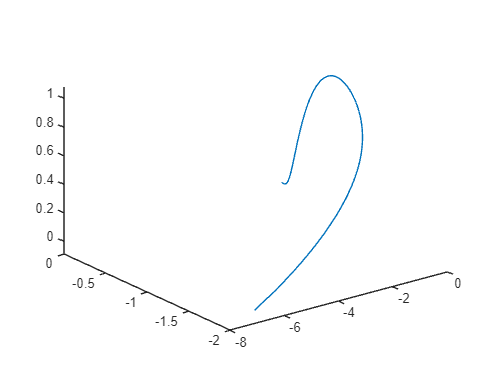


figure
plot3(yfv(1,:),yfv(2,:),yfv(3,:))

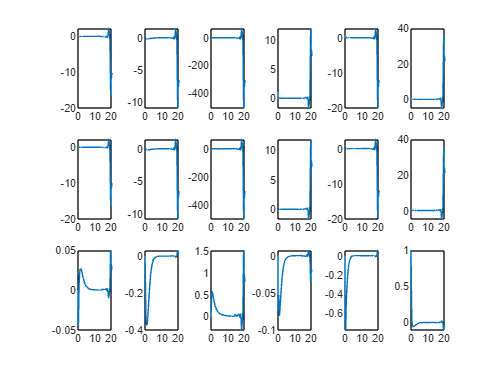


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L] = objective(x)

A = [x(1) x(2) x(3) x(4) x(5) x(6)];

[~, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 20, 0.001,  1e-9);

L = sum((yf{end} - [0;0;0]).^2);

end